Fresh workspace in the appropriate directory

close all; clear all; clc
cd(fileparts(matlab.desktop.editor.getActiveFilename));
cd("..\data-engineering\")

Data Engineering Macros

emg_chan_idxs = 192 + [1,2,3,4,11,12,13,14,21,22,23,24,31,32,33,34,41,42,43,44,51,52,53,54,61,62,63,64,71,72,73,74];
dof_idxs = 1:5; 

Top 3 human learning rate participants from best to worst

data_dir = "D:/FRM/co-adaptive-learning/";
participant_list = ["p-10/healthy/hl/", "p-10/healthy/ml/", "p-05/nonparetic/hl/", "p-05/nonparetic/ml/", "p-08/paretic/hl/"];

## Verify all files exist

for participant_dir = participant_list
    [kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir);
    fprintf("%s\n\t%s\n\t%s\n\t%s\n", participant_dir, kdf_filename, evt_filename, ns5_filename);
end

p-10/healthy/hl/
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/TaskData_20231003-171017.kdf
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/EventParams_20231003-171017.txt
	D:/FRM/co-adaptive-learning/p-10/healthy/hl/20231003-171017-0014.ns5
p-10/healthy/ml/
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/TaskData_20231003-164321.kdf
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/EventParams_20231003-164321.txt
	D:/FRM/co-adaptive-learning/p-10/healthy/ml/20231003-164321-0011.ns5
p-05/nonparetic/hl/
	D:/FRM/co-adaptive-learning/p-05/nonparetic/hl/TaskData_20230308-185106.kdf
	D:/FRM/co-adaptive-learning/p-05/nonparetic/hl/EventParams_20230308-185106.txt
	D:/FRM/co-adaptive-learning/p-05/nonparetic/hl/
p-05/nonparetic/ml/
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/TaskData_20230308-181939.kdf
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/EventParams_20230308-181939.txt
	D:/FRM/co-adaptive-learning/p-05/nonparetic/ml/
p-08/paretic/hl/
	D:/FRM/co-adaptive-learning/p-08/paretic/hl/TaskData_2

NS5 files were not saved for stroke particitipants

curated_participant_list = ["p-05/nonparetic/ml/"]

curated_participant_list = "p-05/nonparetic/ml/"

participant_dir = curated_participant_list(1);
[kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir);
[kdf_table, kdf_events] = load_kdf(kdf_filename, evt_filename, emg_chan_idxs, dof_idxs)

kdf_table = 14965×4 table
     NIP Time            Targets           MAV Features        Kalman Output    
    __________    _____________________    ____________    _____________________

    2.7402e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.7771e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.7855e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.7957e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.8056e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.8221e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.8263e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.8338e+05    0    0    0    0    0    1×32 double     0    0    0    0    0
    2.8434e+05    0    0   

kdf_events = 31×1 struct array with fields:
    ARD
    ART
    ASD
    Acc
    AllPairs
    ApplyBaseline
    AutoPopType
    AutoThresh
    BAmp
    BFreq
    BadEMGChans
    BadUEAElects
    CAR
    CARType
    CtrlMode
    CtrlSpeed
    ETD
    EventID
    Gain
    HideSphrs
    Jitter
    KEMGExtra
    KGainExt
    KGainFlex
    KThreshExt
    KThreshFlex
    KalmanType
    KinematicSrc
    LinkedDOF
    Log10
    ManualSpikes
    ManualStim
    Map
    MvntMat
    MvntName
    NIPTime
    Outcome
    PauseTraining
    Radius
    StimCell
    StimMode
    StimStepSize
    ThreshMode
    ThreshVal
    Tracking
    TrialCntExt
    TrialCntFlex
    TrialSphrs
    TrialTS
    TargOnTS
    InTargTS
    OutTargTS
    SuccessTS
    FailureTS
    TrainingOn


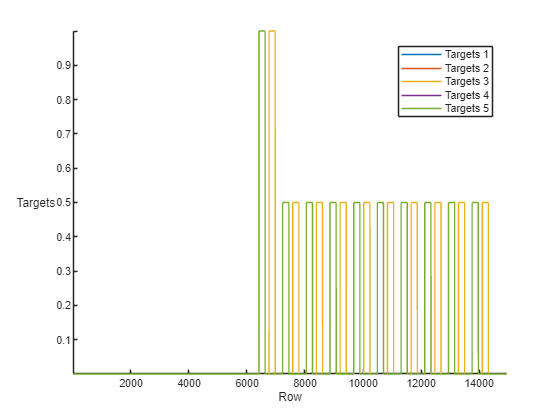

figure;
stackedplot(kdf_table(:,"Targets"))

event_starts_nip = uint32([kdf_events.TargOnTS]');
event_stops_nip = uint32([kdf_events.TrialTS])';
event_stops_nip = event_stops_nip(1:end-1);
session_start_nip = event_starts_nip(1);
session_stop_nip = event_stops_nip(end);
kdf_session_start_idx = find(ismember(kdf_table.("NIP Time"), session_start_nip));
kdf_session_stop_idx = find(ismember(kdf_table.("NIP Time"), session_stop_nip));
kdf_timetable = table2timetable(kdf_table(kdf_session_start_idx:kdf_session_stop_idx,:), 'TimeStep', duration(0,0,0,33))

kdf_timetable = 8168×4 timetable
      Time       NIP Time            Targets           MAV Features        Kalman Output    
    ________    __________    _____________________    ____________    _____________________

    00:00:00    6.6292e+06    0    0    0    0    0    1×32 double     0    0    0    0    0
    00:00:00     6.631e+06    0    0    0    0    0    1×32 double     0    0    0    0    0
    00:00:00    6.6316e+06    1    1    1    1    1    1×32 double     0    0    0    0    0
    00:00:00    6.6322e+06    1    1    1    1    1    1×32 double     0    0    0    0    0
    00:00:00    6.6332e+06    1    1    1    1    1    1×32 double     0    0    0    0    0
    00:00:00    6.6342e+06    1    1    1  

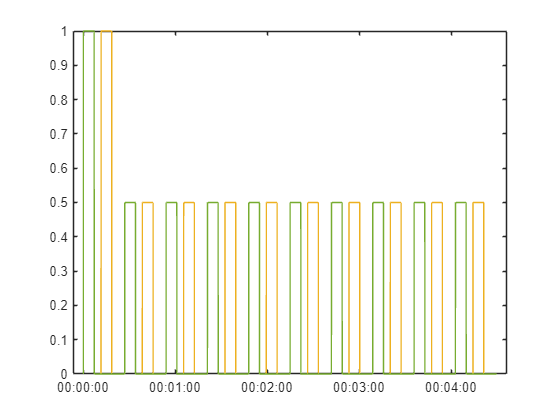

figure
plot(kdf_timetable.Time, kdf_timetable.Targets)

[ns5_header, ns5_data] = jag_deng_utils.read_nsx_file('File', ns5_filename);

[ns5_nip, ns5_start_idxs, ns5_stop_idxs] = compute_ns5_idxs(event_starts_nip, event_stops_nip, kdf_table{1,"NIP Time"}, length(ns5_data));
[ns5_nip, ns5_start_idxs, ns5_stop_idxs] = compute_ns5_idxs(event_starts_nip, event_stops_nip, kdf_table{end,"NIP Time"}, length(ns5_data))
ns5_session_start_idx = find(ismember(ns5_nip, session_start_nip))
ns5_session_stop_idx = find(ismember(ns5_nip, session_stop_nip))

ns5_timetable = timetable(ns5_nip(ns5_session_start_idx:ns5_session_stop_idx), ns5_data(:, ns5_session_start_idx:ns5_session_stop_idx)','SampleRate', ns5_header.Fs, 'VariableNames', ["NIP Time", "EMG"])

ns5_deci_table = retime(ns5_timetable(:,"NIP Time"),'regular', 'SampleRate', 2e3)

emg = double(ns5_timetable.EMG);
emg_dec = NaN(height(ns5_deci_table), width(emg));
parfor i=1:width(emg)
    x = emg(:,i);
    emg_dec(:,i) = decimate(double(x),ns5_header.Fs/2e3);
end

ns5_deci_table.("EMG") = emg_dec

ns5_filt_table = bandpass(ns5_deci_table(:,"EMG"), [20 850]) %from meta paper

normalized_signals = normalize(ns5_filt_table.EMG, 1, 'range', [-1, 1]);
centered_signals = normalize(single(normalized_signals), 1, 'center', "mean");
ns5_norm_table = ns5_dectable(:,"NIP Time");
ns5_norm_table.("EMG") = centered_signals

x = ns5_norm_table.("EMG");
y = x(1:end-33,:)-x(34:end,:)
mav = movmean(abs(y), [599 0], 1)
mav_ffc_table = ns5_norm_table(601:end-33,"NIP Time");
mav_ffc_table.("EMG") = mav(601:end,:)


figure
tlo = tiledlayout('flow');
i = 5;
nexttile
hold on
plot(ns5_timetable.Time, ns5_timetable.EMG(:,i))
plot(ns5_deci_table.Time, ns5_deci_table.EMG(:,i))
plot(ns5_deci_table.Time, ns5_filt_table.EMG(:,i))
hold off
nexttile
hold on
plot(ns5_deci_table.("NIP Time"), centered_signals(:,i))
plot(kdf_timetable.("NIP Time"), kdf_timetable.Targets)
plot(kdf_timetable.("NIP Time"), kdf_timetable.("MAV Features")(:,i)/100)
plot(mav_ffc_table.("NIP Time"), mav_ffc_table.("MAV")(:,i), 'Color','k', 'LineWidth',1.5)
hold off

ns5_norm_table = mav_ffc_table;
figure
tlo =tiledlayout(2,5);
nexttile
histogram(ns5_norm_table.EMG(:,i), ceil(2*nthroot(height(ns5_norm_table),3)), 'Normalization','probability')
for j = find(ismember(ns5_norm_table.("NIP Time"), kdf_timetable.("NIP Time")([find(sum(diff(kdf_timetable.Targets~=0), 2)==5)])))'
    nexttile
    histogram(ns5_norm_table.EMG(j:j+40e3,i), ceil(2*nthroot(40e3,3)), 'Normalization','probability')
    box off
    title(sprintf("Trial %02d", j))
    xlim([0, 0.3])
    ylim([0, 0.1])
end

It seems that each trial might have its own distro, so the MI shoud be calculated for each trial at different lags

n_trials = 9;
trial_idxs = find(ismember(ns5_norm_table.("NIP Time"), kdf_timetable.("NIP Time")([find(sum(diff(kdf_timetable.Targets~=0), 2)==5)])))';
trial_idxs = [1, trial_idxs];
trial_length = 20*2e3; % 20 sec at 2 kHz
trial_count = 0;
n_chans = width(ns5_norm_table.EMG);
n_lags = 300e-3*2e3; % 300 msec at 2 kHz
min_mi_scores = NaN(n_trials, n_chans);

f = waitbar(0,'1','Name','Computing MI scores...', 'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);
tic

for trial_idx = trial_idxs
    trial_count = trial_count+1;
    for chan_idx = 1:n_chans
        x = ns5_norm_table.EMG(trial_idx:trial_idx+trial_length,chan_idx);
        mi_scores = zeros(n_lags,1);
        parfor i_lag = 1:n_lags
            x_lag = x(1+i_lag:end);
            x_ref = x(1:end-i_lag);
            mi_scores(i_lag) = mi_utils.mi_cont_cont(x_ref, x_lag, 5);
        end
        min_mi_score = find(islocalmin(mi_scores),1);
        min_mi_scores(trial_count, chan_idx) = min_mi_score;
        waitbar(chan_idx/n_chans,f,sprintf('T%02d CH%02d - %0.3f', trial_count, chan_idx, toc/60))
    end
end
delete(f)
fprintf("Loop Time = %0.3f", toc/60)

save('..\..\temp-data\mav_min_mi_scores.mat', "min_mi_scores")

figure();
plot(mi_scores)

figure();
tlo = tiledlayout('flow');
nexttile; surf(min_mi_scores)
nexttile; hold on; boxchart(min_mi_scores'); plot(mean(min_mi_scores,2), 'd', 'MarkerFaceColor','auto'); hold off
nexttile; histogram(min_mi_scores)
median(min_mi_scores(1:8,:),'all')
quantile(min_mi_scores, 0.75, 'all')
quantile(min_mi_scores, 0.60, 'all')
quantile(min_mi_scores, 0.50, 'all')
quantile(min_mi_scores, 0.25, 'all')

tau = 70;
% cao_scores = NaN(n_trials, n_chans);
trial_idxs = find(ismember(ns5_norm_table.("NIP Time"), kdf_timetable.("NIP Time")([find(sum(diff(kdf_timetable.Targets~=0), 2)==5)])))';
trial_idxs = [1, trial_idxs];

trial_count = 0;

f = waitbar(0,'1','Name','Computing Cao scores...', 'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(f,'canceling',0);
tic

% trial_count = 3;
for trial_idx = trial_idxs(trial_count+1:end)
    trial_count = trial_count+1;
    for chan_idx = 1:n_chans
        emg_sig = ns5_norm_table.EMG(trial_idx:trial_idx+trial_length,chan_idx);
        [E1, E2] = cao_utils.cao_deneme(emg_sig, tau, 10);
        E1_clean = fillmissing(E1,'previous', 'EndValues','nearest');
        x0= 1;
        xn= length(E1_clean);
        y0= E1_clean(1);
        yn= E1_clean(end);
        x= x0:xn;
        E1_dline = (yn-y0)/(xn-x0)*(x-x0)+y0;
        cao_score = find(islocalmax(E1_clean-E1_dline),1);
        try
            cao_scores(trial_count, chan_idx) = cao_score;
        catch
            cao_scores(trial_count, chan_idx) = -1;
        end
        waitbar(chan_idx/n_chans, f, sprintf('T%02d -CH%02d - %0.3f', trial_count, chan_idx, toc/60))
    end
end

delete(f)
fprintf("Loop Time = %0.3f", toc/60)
disp(max(cao_scores,[],'all'))

save('..\..\temp-data\mav_cao_scores.mat', "cao_scores")

writetimetable(ns5_norm_table, '..\..\temp-data\mav_norm.csv')

figure();
tlo = tiledlayout('flow');
nexttile; surf(cao_scores)
nexttile; hold on; boxchart(cao_scores'); plot(mean(cao_scores,2), 'd', 'MarkerFaceColor','auto'); hold off
nexttile; histogram(cao_scores)

figure
plot(mi_scores)
hold on
xline(find(islocalmin(mi_scores),10))
hold off
box off

i_lag = 1;
x_ref = x(1:end-i_lag);
x_lag = x(1+i_lag:end);
figure();
h = animatedline;
for t = 1:100:length(x_ref)
    addpoints(h, x_ref(t), x_lag(t));
    drawnow
end

## Helper Functions

function [kdf_filename, evt_filename, ns5_filename] = get_filenames(data_dir, participant_dir)
kdf_regex = "Task*.kdf";
evt_regex = "Event*.txt";
ns5_regex = "*.ns5";

dir_out = dir(strcat(data_dir, participant_dir, kdf_regex));
kdf_filename = strcat(data_dir, participant_dir, dir_out.name);

dir_out = dir(strcat(data_dir, participant_dir, evt_regex));
evt_filename = strcat(data_dir, participant_dir, dir_out.name);

dir_out = dir(strcat(data_dir, participant_dir, ns5_regex));
ns5_filename = convertStringsToChars(strcat(data_dir, participant_dir, dir_out.name));
end
function [kdf_table, kdf_events] = load_kdf(kdf_filename, evt_filename, emg_chan_idxs, dof_idxs)
[Kinematics, Features, Targets, Kalman, NIPTime] = jag_deng_utils.read_kdf_file(kdf_filename);
kdf_table = table(NIPTime', Targets(dof_idxs,:)', Features(emg_chan_idxs,:)', Kalman(dof_idxs, :)', ...
    'VariableNames', ["NIP Time", "Targets", "MAV Features", "Kalman Output"]);
kdf_events = jag_deng_utils.read_event_params(evt_filename);
end
function [ns5_nip, ns5_start_idxs, ns5_stop_idxs] = compute_ns5_idxs(event_starts_nip, event_stops_nip, kdf_nip_ref, ns5_length)
% ns5_nip = (kdf_nip_ref:(kdf_nip_ref+ns5_length-1))';
ns5_nip = flip(kdf_nip_ref:-1:kdf_nip_ref-ns5_length+1)';
ns5_start_idxs = find(ismember(ns5_nip, event_starts_nip));
ns5_stop_idxs = find(ismember(ns5_nip, event_stops_nip));
end